% Clear Workspace
clear all
clc

% Read STL File
stl1 = stlread("Test Objects\cubeWithHole.STL");
% stl1 = stlread("Test Objects\cylinder.STL");

% Create UniformSliceGeneratorObject
sliceHeight = 4;
uSGO1 = FlatUniformSliceGenerator(stl1, sliceHeight)

uSGO1 =   FlatUniformSliceGenerator with properties:

                 obj: []
    connectivityList: [184×3 double]
       numOfElements: 184
              points: [92×3 int64]
      sliceThickness: 4
           slicePath: []
           slicerTol: 0.0100



test = uSGO1.slice(0)

test =    100     0     0     1
   100   100     0     1
   100   100     0     1
   100   100     0     1
   100   100     0     1
   100   100     0     1
   100   100     0     1
   100   100     0     1
   100   100     0     1
   100   100     0     1


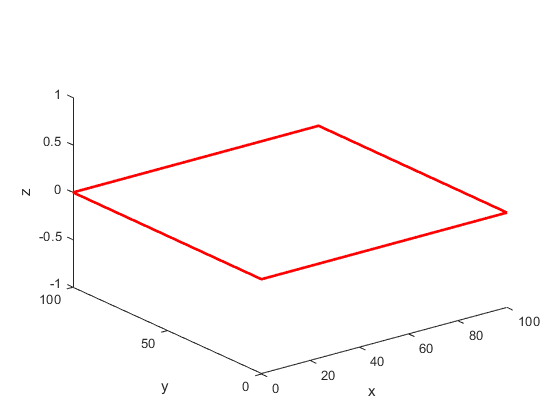

plot3(test(:,1), test(:,2), test(:,3),'-r','LineWidth',2);
xlabel('x')
ylabel('y')
zlabel('z')


% Generate
figure(3)
uSGO1.generateSlices()

ans =   FlatUniformSliceGenerator with properties:

                 obj: []
    connectivityList: [184×3 double]
       numOfElements: 184
              points: [92×3 int64]
      sliceThickness: 4
           slicePath: [1122×4 int64]
           slicerTol: 0.0100


op = uSGO1.getSlicePath()

op = 1122×4 int64 matrix
   100     0     0     1
   100   100     0     1
   100   100     0     1
   100   100     0     1
   100   100     0     1
   100   100     0     1
   100   100     0     1
   100   100     0     1
   100   100     0     1
   100   100     0     1


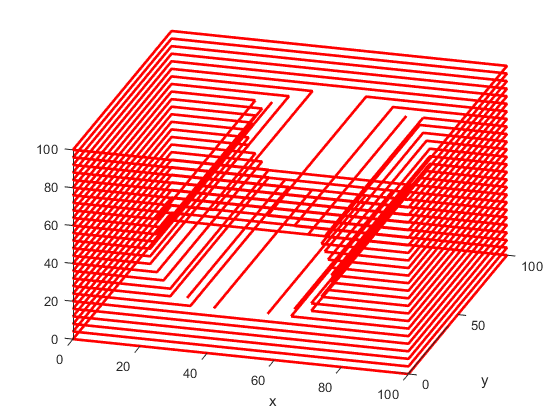


% Show
figure(4)

for i = 0:sliceHeight:max(op(:,3))
    
    zPlotPoints = op(op(:,3) == i,:);
    
    for j = 1:max(zPlotPoints(:,4))
    
        pathPlotPoints = zPlotPoints(zPlotPoints(:,4) == j,:);
        plot3(pathPlotPoints(:,1), pathPlotPoints(:,2), pathPlotPoints(:,3),'-r','LineWidth',2);
        hold on

    end

end

xlabel('x')
ylabel('y')
view(3);
hold on